传递函数：$\frac{1}{s^2 }$

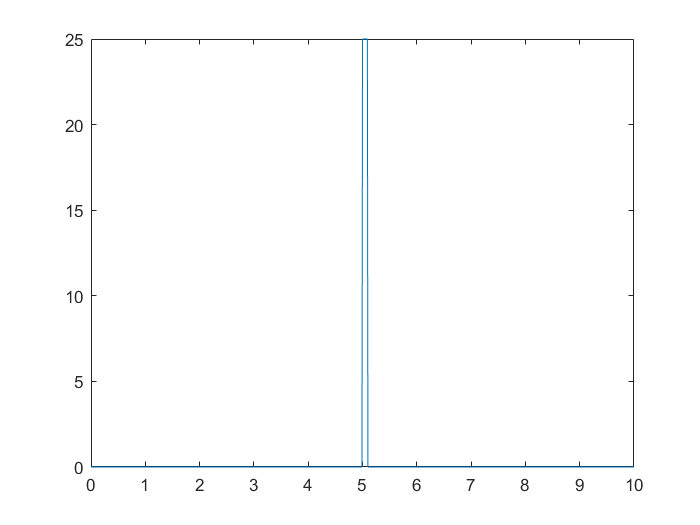

clc,clear
s=tf('s');
sysG=0.0002/s^2;  %传递函数：1/s^2
t=0:0.01:10;
u1=[zeros(1,500),25*ones(1,10),zeros(1,491)];  %输入，其中0.1s的幅值为25的短脉冲输入
[y1]=lsim(sysG,u1,t);  
% y = lsim(sys,u,t) 返回系统响应 y，在与输入相同的时间 t 采样。 
% 对于单输出系统，y 是与 t 长度相同的向量。 
% 对于多输出系统，y 是一个数组，其行数与时间样本数 (length(t)) 一样多，列数与 sys.path 中的输出数一样多。
% 此语法不会生成绘图。
ff=180/pi; 
y1=ff*y1;  %转换为角度值
plot(t,u1);

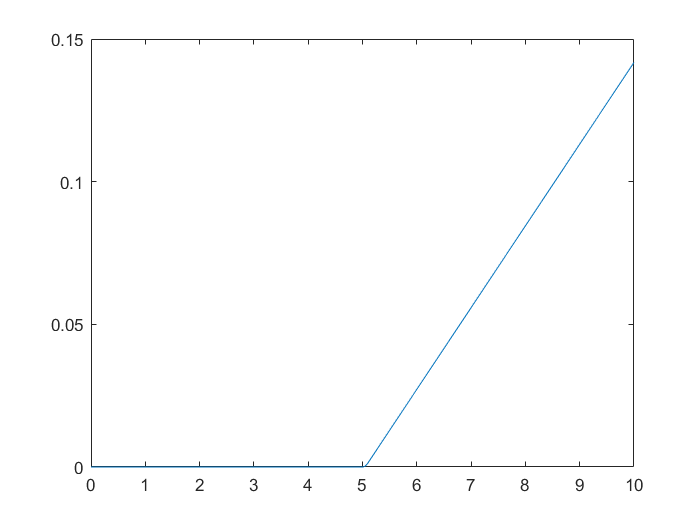

plot(t,y1);